syms s k_p T_i T T_t k_u k_r v_star

% Laplace-Transformierte des Rampensignals
W_p = v_star / s^2;


% Definieren Sie die Übertragungsfunktion G_wp(s) basierend auf den bereitgestellten Informationen
G_wp = (T_i*s +1) / ...
       (  (T_i*T*T_t)/(k_p*k_r*k_u)*s^4 + (T_i*(T+T_t))/(k_p*k_r*k_u)*s^3 + T_i/k_p * (1 + 1/(k_r*k_u))*s^2 + (1/k_p + T_i)*s + 1);

disp([G_wp]);

$$\frac{T_{i}\,s+1}{s\,\left(T_{i}+\frac{1}{k_{p}}\right)+\frac{T_{i}\,s^{2}\,\left(\frac{1}{k_{r}\,k_{u}}+1\right)}{k_{p}}+\frac{T_{i}\,s^{3}\,\left(T+T_{t}\right)}{k_{p}\,k_{r}\,k_{u}}+\frac{T\,T_{i}\,T_{t}\,s^{4}}{k_{p}\,k_{r}\,k_{u}}+1}$$

Ausgabe Y_p(s)

Y_p = G_wp * W_p;

Regelabweichung

E_p = W_p - Y_p;

Endwertsatz, um den stationären Fehler e_y zu finden

e_y = limit(s * E_p, s, 0);
disp('Der stationäre Schleppabstand e_y ist:');

Der stationäre Schleppabstand e_y ist:


disp(e_y);

$$\frac{v_{\mathrm{star}}}{k_{p}}$$

kp = 1 bestimmt durch e_y = 0.1/kp --> kp = 1

kp = 1

kp = 1

ey = 0.1/1;

c) Rampenantwort simulieren

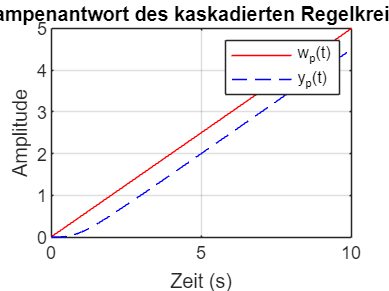

% Parameter definieren
kp = 1;
kr = 0.344014;
ku = P_p_k; 
Ti = 0.246830;
T = P_p_T; 
Tt = P_p_Tt; 
v_star = 0.5; 

% Übertragungsfunktion definieren
numerator = [Ti 1];
denominator = [(Ti*T*Tt)/(kp*kr*ku) (Ti*(T+Tt))/(kp*kr*ku) Ti/kp*(1 + 1/(kr*ku)) (1/kp + Ti) 1];
G_wp = tf(numerator, denominator);

% Simulationszeit definieren
t = 0:0.01:10; % 10 Sekunden lang von 0 bis 10 mit 0.01 Sekunden Schritten

% Rampensignal erzeugen
w_p = v_star * t;

% Systemantwort simulieren
[y_p, t_out] = lsim(G_wp, w_p, t);

%Grafische Darstellung der Ergebnisse
figure;
plot(t_out, w_p, 'r', t_out, y_p, 'b--');
xlabel('Zeit (s)');
ylabel('Amplitude');
title('Rampenantwort des kaskadierten Regelkreises');
legend('w_p(t)', 'y_p(t)');
grid on;

d) Ab welcher Reglerverstärkung k_p wäre der kaskadierte Regelkreis instabil?

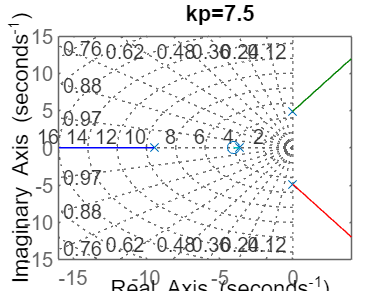

kp=7.5;
denominator = [(Ti*T*Tt)/(kp*kr*ku) (Ti*(T+Tt))/(kp*kr*ku) Ti/kp*(1 + 1/(kr*ku)) (1/kp + Ti) 1];
G_wp = tf(numerator, denominator);
r = rlocus(G_wp);
rlocus(G_wp);
grid on;
title('kp=7.5');

Ab ca. kp=7.5 wird der RK instabil.